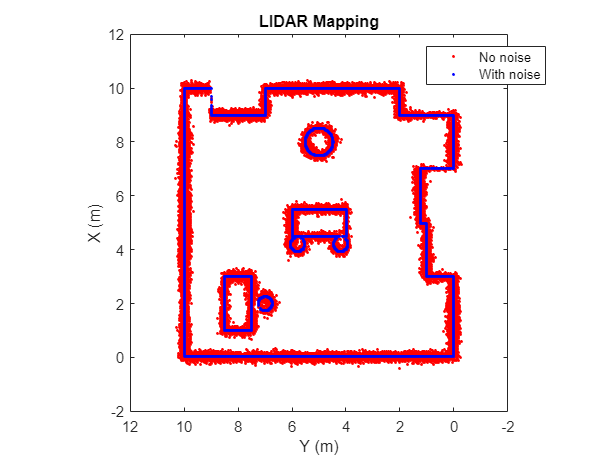

scan_pts = [];
scan_pts_noise = [];

for n = 1:width(robot_state_history)
    robot_state = robot_state_history(:,n);
    ranges = lidar_history(:,n);
    
    pts_i = [cos(robot_state(3) + angles) .* ranges sin(robot_state(3) + angles) .* ranges] + robot_state(1:2)';
    noise_i = normrnd(zeros(size(ranges)),ones(size(ranges))*0.1);
    pts_i_noise = [cos(robot_state(3) + angles) .* (ranges + noise_i) sin(robot_state(3) + angles) .* (ranges+noise_i)] + robot_state(1:2)';
    scan_pts = [scan_pts; pts_i];
    scan_pts_noise = [scan_pts_noise; pts_i_noise];

end

plot(scan_pts_noise(:,1), scan_pts_noise(:,2), '.r');  hold on
plot(scan_pts(:,1), scan_pts(:,2), '.b');
 hold off
axis square
view(-90,90);

xlabel("X (m)")
ylabel("Y (m)")
title("LIDAR Mapping")

legend(["No noise", "With noise"], "Location","northeast")


% hold on
% roomshow(roomspec)
% hold off